%part a
%define angles given
theta2 = 40:5:60;
theta4 = [70, 76, 83, 91, 100];

%get k1 k2 k3
A = []


A =

     []



B = []


B =

     []



for i = 1:length(theta2)
    temp1 = [(cosd(theta4(i))) (-1 * (cosd(theta2(i)))) (1)];
    temp2 = cosd(theta2(i)-theta4(i));
    A = [A; temp1];
    B = [B; temp2];
end
%link_ratios = lsqr(A,B); alternative solution
sol = linsolve(A,B);
k1 = sol(1,1)

k1 = 1.0201

k2 = sol(2,1)

k2 = 1.6053

k3 = sol(3,1)

k3 = 1.7464

%get link lengths
d = 180;
a = abs(d/k1);
c = abs(d/k2);
b = abs(sqrt(a * a + c * c + d * d - 2 * a * c * k3));
fprintf("a %d b %d c %d", a,b,c)

a 1.764601e+02 b 8.367472e+01 c 1.121312e+02

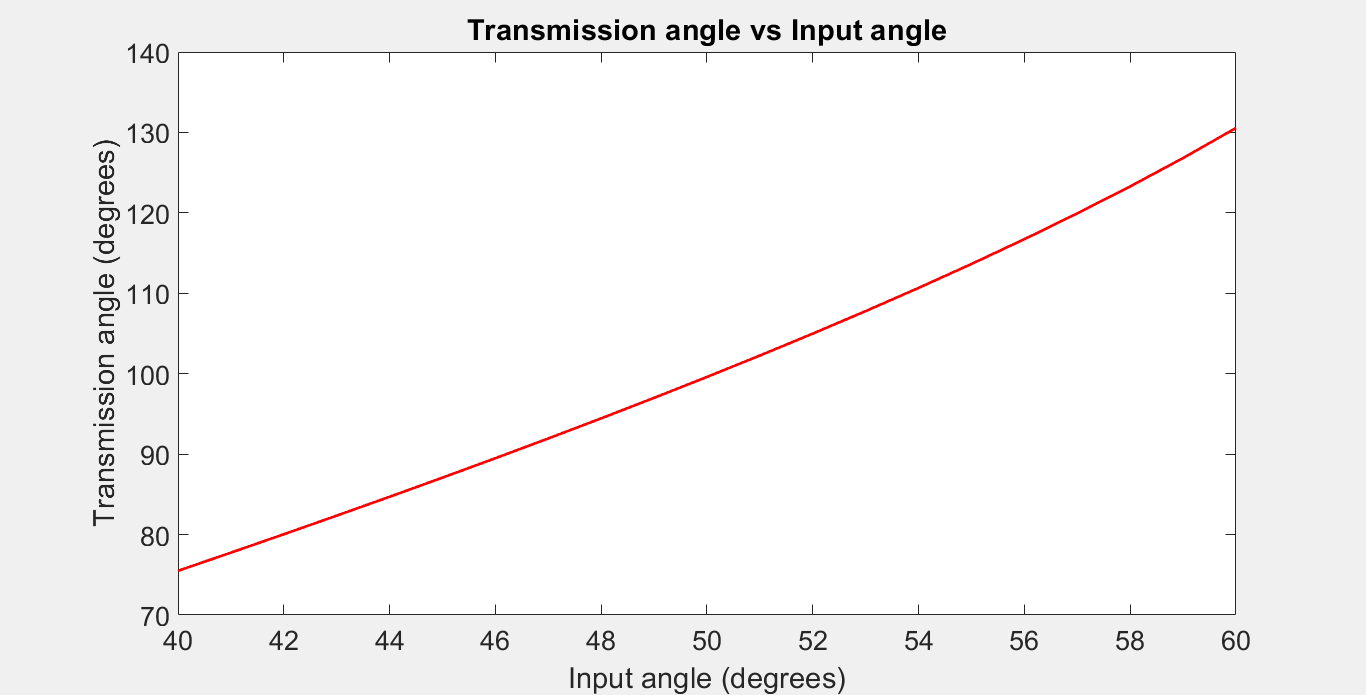

%part b
% transmission angle
inputAngle = 40:1:60;
transAngle = acosd((b*b + c*c - (a*a+d*d) + 2 * a * d * cosd(inputAngle))/ (2 * b * c));
plot(inputAngle, transAngle, 'r', 'LineWidth',2)
figure(1)
title('Transmission angle vs Input angle')
xlabel('Input angle (degrees)')
ylabel('Transmission angle (degrees)')
set(gcf,'Position', get(0,'Screensize'));
set(gcf,'Visible','on')
set(gca, 'FontSize', 20)

%part c
%relationship of theta2 to theta4
x = theta2

x =     40    45    50    55    60


y = theta4

y =     70    76    83    91   100


for i= 1:5
    xy(i) = x(i) * y(i)
end

xy =         2800        3420        4150        5005        6000


xy =         2800        3420        4150        5005        6000


xy =         2800        3420        4150        5005        6000


xy =         2800        3420        4150        5005        6000


xy =         2800        3420        4150        5005        6000


ySquared = y.^2

ySquared =         4900        5776        6889        8281       10000


xSquared = x.^2

xSquared =         1600        2025        2500        3025        3600


aR = (sum(y)*sum(xSquared) - sum(x)*sum(xy)) / (5 * sum(xSquared) - sum(x).^2)

aR = 9

bR = (5 * sum(xy) - sum(x) * sum(y)) / (5 * sum(xSquared) - sum(x).^2)

bR = 1.5000

theta2C = 40:1:60

theta2C =     40    41    42    43    44    45    46    47    48    49    50    51    52    53    54    55    56    57    58    59    60


theta4C = aR + bR * theta2C

theta4C =    69.0000   70.5000   72.0000   73.5000   75.0000   76.5000   78.0000   79.5000   81.0000   82.5000   84.0000   85.5000   87.0000   88.5000   90.0000   91.5000   93.0000   94.5000   96.0000   97.5000   99.0000


sError = zeros(1,21)

sError =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


%get structural errors
for j = 1:length(theta2C)
    sError(j) = k1 * cosd(theta4C(j)) - k2 * cosd(theta2C(j)) + k3 - cosd(theta2C(j) - theta4C(j))
end

sError =     0.0076         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


sError =     0.0076    0.0050         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


sError =     0.0076    0.0050    0.0026         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


sError =     0.0076    0.0050    0.0026    0.0004         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


sError =     0.0076    0.0050    0.0026    0.0004   -0.0015         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


sError =     0.0076    0.0050    0.0026    0.0004   -0.0015   -0.0032         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


sError =     0.0076    0.0050    0.0026    0.0004   -0.0015   -0.0032   -0.0047         0         0         0         0         0         0         0         0         0         0         0         0         0         0


sError =     0.0076    0.0050    0.0026    0.0004   -0.0015   -0.0032   -0.0047   -0.0059         0         0         0         0         0         0         0         0         0         0         0         0         0


sError =     0.0076    0.0050    0.0026    0.0004   -0.0015   -0.0032   -0.0047   -0.0059   -0.0068         0         0         0         0         0         0         0         0         0         0         0         0


sError =     0.0076    0.0050    0.0026    0.0004   -0.0015   -0.0032   -0.0047   -0.0059   -0.0068   -0.0075         0         0         0         0         0         0         0         0         0         0         0


sError =     0.0076    0.0050    0.0026    0.0004   -0.0015   -0.0032   -0.0047   -0.0059   -0.0068   -0.0075   -0.0079         0         0         0         0         0         0         0         0         0         0


sError =     0.0076    0.0050    0.0026    0.0004   -0.0015   -0.0032   -0.0047   -0.0059   -0.0068   -0.0075   -0.0079   -0.0079         0         0         0         0         0         0         0         0         0


sError =     0.0076    0.0050    0.0026    0.0004   -0.0015   -0.0032   -0.0047   -0.0059   -0.0068   -0.0075   -0.0079   -0.0079   -0.0077         0         0         0         0         0         0         0         0


sError =     0.0076    0.0050    0.0026    0.0004   -0.0015   -0.0032   -0.0047   -0.0059   -0.0068   -0.0075   -0.0079   -0.0079   -0.0077   -0.0071         0         0         0         0         0         0         0


sError =     0.0076    0.0050    0.0026    0.0004   -0.0015   -0.0032   -0.0047   -0.0059   -0.0068   -0.0075   -0.0079   -0.0079   -0.0077   -0.0071   -0.0062         0         0         0         0         0         0


sError =     0.0076    0.0050    0.0026    0.0004   -0.0015   -0.0032   -0.0047   -0.0059   -0.0068   -0.0075   -0.0079   -0.0079   -0.0077   -0.0071   -0.0062   -0.0049         0         0         0         0         0


sError =     0.0076    0.0050    0.0026    0.0004   -0.0015   -0.0032   -0.0047   -0.0059   -0.0068   -0.0075   -0.0079   -0.0079   -0.0077   -0.0071   -0.0062   -0.0049   -0.0033         0         0         0         0


sError =     0.0076    0.0050    0.0026    0.0004   -0.0015   -0.0032   -0.0047   -0.0059   -0.0068   -0.0075   -0.0079   -0.0079   -0.0077   -0.0071   -0.0062   -0.0049   -0.0033   -0.0013         0         0         0


sError =     0.0076    0.0050    0.0026    0.0004   -0.0015   -0.0032   -0.0047   -0.0059   -0.0068   -0.0075   -0.0079   -0.0079   -0.0077   -0.0071   -0.0062   -0.0049   -0.0033   -0.0013    0.0011         0         0


sError =     0.0076    0.0050    0.0026    0.0004   -0.0015   -0.0032   -0.0047   -0.0059   -0.0068   -0.0075   -0.0079   -0.0079   -0.0077   -0.0071   -0.0062   -0.0049   -0.0033   -0.0013    0.0011    0.0039         0


sError =     0.0076    0.0050    0.0026    0.0004   -0.0015   -0.0032   -0.0047   -0.0059   -0.0068   -0.0075   -0.0079   -0.0079   -0.0077   -0.0071   -0.0062   -0.0049   -0.0033   -0.0013    0.0011    0.0039    0.0070


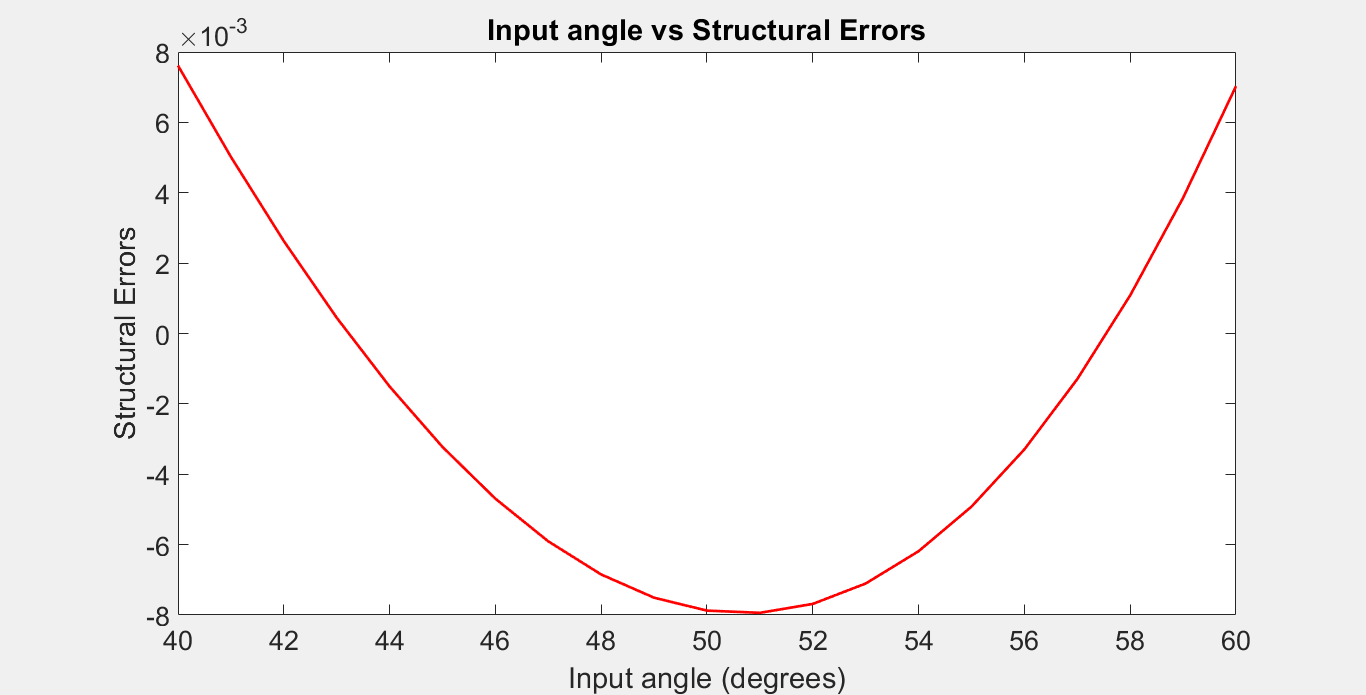

figure(2)
plot(theta2C, sError, 'r', 'LineWidth',2)
title('Input angle vs Structural Errors')
xlabel('Input angle (degrees)')
ylabel('Structural Errors')
set(gcf,'Position', get(0,'Screensize'));
set(gcf,'Visible','on')
set(gca, 'FontSize', 20)